# **Vision Artificial. GIEC-GITT.**

# **Sistemas de Vision Artificial. GII-GIC-GISI.**

**  Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Franck Michael Fierro Chicaiza**

**Fecha: 20/11/2023**

# Tema 4. Ejercicio 4. *Local features*

## Localización de esquinas utilizando el algoritmo FAST

El objetivo de esta práctica es comprobar la capacidad de las características FAST para localizar esquinas en imágenes diferentes. Para ello:

- Utilice `corners = detectFASTFeatures(I)` sobre la imagen 'ladrillos1.jpg', y visualice las esquinas sobre ella con la instrucción `plot(corners.selectStrongest(25))`;

- Modifique el número de esquinas a detectar, para comprobar que las que se incorporan son más débiles.

- Pruebe sobre diferentes imágenes (texture-pattern2.png, rice.tif, etc.) para identificar aquellas en las que estas características pueden resultar más útiles.

imfinfo('./Imagenes/ladrillos1.jpg').ColorType

ans = 'truecolor'

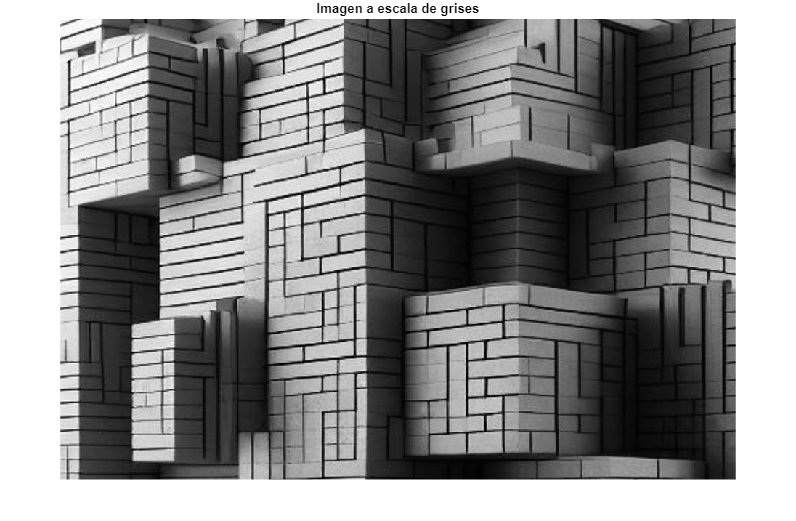

% Cargamos la imagen 
I = rgb2gray(imread('./Imagenes/ladrillos1.jpg'));

figure, imshow(I); title('Imagen a escala de grises');

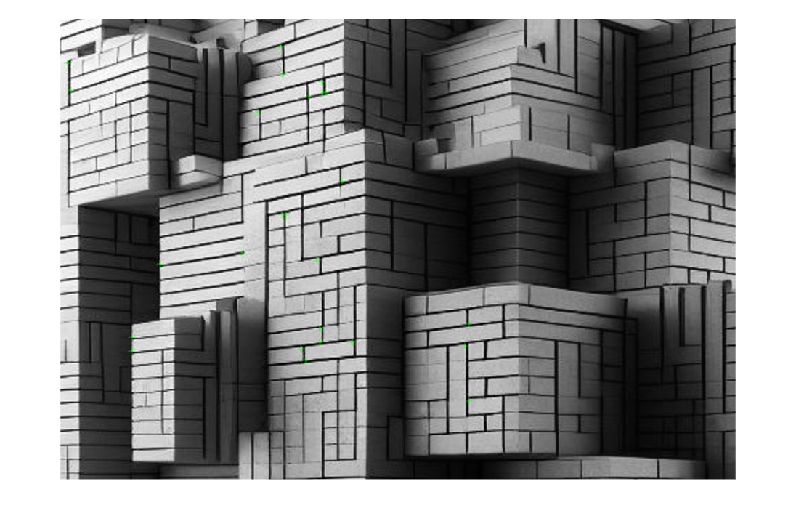

%
corners = detectFASTFeatures(I);
figure, imshow(I);
hold on,
plot(corners.selectStrongest(25));

## Uso de características LBP para distinguir imágenes con texturas diferentes

El objetivo de este ejercicio es verificar el comportamiento de las caracteristicas LBP en imágenes con texturas diferentes. Para ello:

- Abra y muestre las imágenes texture-canvas.png, gotas.jpg, ladrillos2.jpg, ladrillos3.jpg y ladrillos4.jpg y calcule sus características LBP con la instrucción `LBPImag1 = extractLBPFeatures(Imag1,'Upright',false).`

- Visualice las características con `bar(LBPImag1)`. ¿Se parecen entre sí las características de las distintas imágenes?

- Calcule la distancia entre las características LBP de ladrillos3.jpg y cada una de las demás imágenes, utilizando la instrucción `DistImag1_2 = norm (LBPImag1 - LBPImag2)`. Analice los resultados. ¿Son coherentes con lo que se puede verificar visualmente?

imfinfo('./Imagenes/texture-canvas.png').ColorType

ans = 'grayscale'

imfinfo('./Imagenes/gotas.jpg').ColorType

ans = 'truecolor'

imfinfo('./Imagenes/ladrillos2.jpg').ColorType

ans = 'truecolor'

imfinfo('./Imagenes/ladrillos3.jpg').ColorType

ans = 'truecolor'

imfinfo('./Imagenes/ladrillos4.jpg').ColorType

ans = 'truecolor'

% Cargamos las imagenes
Imag = {imread('./Imagenes/texture-canvas.png'), ...
    rgb2gray(imread('./Imagenes/gotas.jpg')), ...
    rgb2gray(imread('./Imagenes/ladrillos2.jpg')), ...
    rgb2gray(imread('./Imagenes/ladrillos3.jpg')), ...
    rgb2gray(imread('./Imagenes/ladrillos4.jpg'))};

figure,
subplot(2,3,1), imshow(Imag{1}); title('Imagen 1');
subplot(2,3,2), imshow(Imag{2}); title('Imagen 2');
subplot(2,3,3), imshow(Imag{3}); title('Imagen 3');
subplot(2,2,3), imshow(Imag{4}); title('Imagen 4');
subplot(2,2,4), imshow(Imag{5}); title('Imagen 5');
% Calculamos las caracteristicas LBP
LBPImag = {extractLBPFeatures(Imag{1}, 'Upright', false), ...
    extractLBPFeatures(Imag{2}, 'Upright', false), ...
    extractLBPFeatures(Imag{3}, 'Upright', false), ...
    extractLBPFeatures(Imag{4}, 'Upright', false), ...
    extractLBPFeatures(Imag{5}, 'Upright', false)};

% Visualizamos las caracteristicas
figure,
subplot(2,3,1), bar(Imag{1}); title('Imagen 1');
subplot(2,3,2), bar(Imag{2}); title('Imagen 2');
subplot(2,3,3), bar(Imag{3}); title('Imagen 3');
subplot(2,2,3), bar(Imag{4}); title('Imagen 4');
subplot(2,2,4), bar(Imag{5}); title('Imagen 5');

Comentarios: